# Evaluación

Ana Itzel Hernández García A01737526

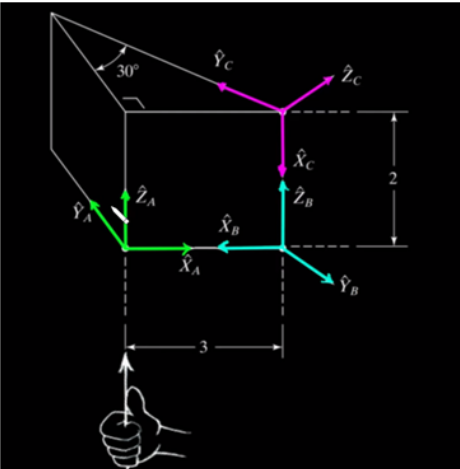

Se limpian las variables

clear all
close all
clc

Delcaración de variables simbólicas 

syms th1(t) th2(t) l1 l2 t

% Configuración del robot, de cada GDL
RP = [0, 0];

% Creación del vector de coordenadas articulares
Q = [th1, th2];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Articulación 1

Posición de la articulación 1 a 2

P(:,:,1) = [
            l1;
            0;
            0;
           ];

Matriz de rotación de la junta 1 a 2

R(:,:,1) = [
             cos(th1)   -sin(th1)     0;
             sin(th1)    cos(th1)     0;
             0           0            1
             ]*rotZ(180);

## Articulación 2

Posición de la articulación 2 a 3

P(:,:,2) = [
            0;
            0;
            l2
           ];

Matriz de rotación 2 a 3

R(:,:,2) = [
             cos(th2)   -sin(th2)     0;
             sin(th2)    cos(th2)     0;
             0           0            1
             ]*rotY(-90)*rotZ(-180); 

## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las matrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las matrices de tranformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i)); T(:,:,i)

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\\ -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T1


$$ans = \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\\ -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} 0 & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T2


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{1}\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En las matrices locales podemos observar que efectivamente en la ultima columna se respeta el vector de posción, mientas que en global concentra las pocisiones de las articulaciones.

De igual manera las matrices locales contienen cada matriz de rotación 3x3 de cada rotación mientras la global contiene la general del sistema

% Inicialización de jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end

## Despliegue

disp('Jacobiano lineal obtenido de forma analítica'); Jv_a = simplify(Jv_a);

Jacobiano lineal obtenido de forma analítica


disp('Jacobiano angular obtenido de forma ananlítica'); Jw_a = simplify(Jw_a);

Jacobiano angular obtenido de forma ananlítica


disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \left(\begin{array}{c} 0\\ l_{1}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\\ 0 \end{array}\right)$$

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}\right)$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end

